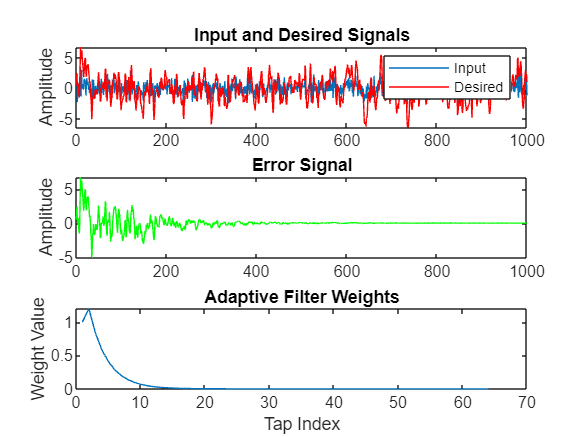

% LMS Algorithm for Active Noise Control
clear all; close all; clc;

% Parameters
mu = 0.01;      % Step size
M = 64;         % Filter order

% Input signal (noise reference)
x = randn(1000,1);

% Desired signal (noise to be cancelled)
d = filter([1 0.5],[1 -0.7],x);

% Initialize weight vector
w = zeros(M,1);

% Buffers
x_buf = zeros(M,1);
y_buf = zeros(length(d),1);

% Main loop
for n = (M+1):length(x)
    
    % Shift input buffer
    x_buf = [x(n:-1:n-M+1)]; % Fixed indexing
    
    % FIR filter output
    y = w'*x_buf;
    y_buf(n) = y;
    
    % Error signal
    e = d(n) - y;
    
    % Update weight vector
    w = w + mu * e * x_buf;
    
end

% Plot results
figure;
subplot(3,1,1);
plot(x); hold on; plot(d,'r'); legend('Input','Desired');
ylabel('Amplitude');
title('Input and Desired Signals');

subplot(3,1,2);
plot(d-y_buf,'g'); 
ylabel('Amplitude');
title('Error Signal');

subplot(3,1,3);
plot(w);
ylabel('Weight Value');
xlabel('Tap Index');
title('Adaptive Filter Weights');